Lab Assignment 1

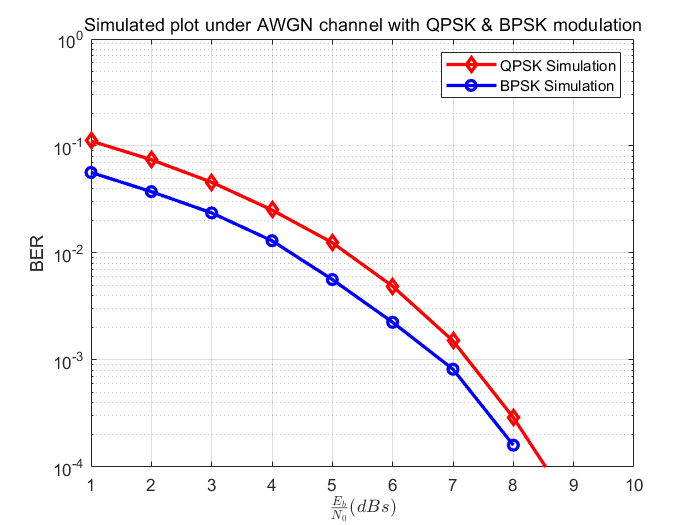

close all;
clc;

% Number of bits to be transmitted
N = 10^5;

% For BPSK

inputSignal = rand(1,N) > 0.5;
convertedSignal = 2*inputSignal - 1; % Converting 0,1 to -1,1

% For QPSK

inputSig1 = rand(1,N) > 0.5;
convertedSig1 = 2*inputSig1 - 1; % Converting 0,1 to -1,1

inputSig2 = rand(1,N) > 0.5;
convertedSig2 = 2*inputSig2 - 1; % Converting 0,1 to -1,1

convertedSig = convertedSig1 + 1i*convertedSig2; % si + j*sq (IQ signal)

Eb_N0_db = (1:11); % SNR range in decibels

for i = 1:length(Eb_N0_db)
    
    noise = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N)); % AWGN Noise
    addingNoise = power(10,-Eb_N0_db(i)/20) * noise; % noise normalizing
    
    % Adding noise to BPSK & QPSK modulated signal
    BPSKsig = convertedSignal + addingNoise;
    QPSKsig = convertedSig + addingNoise;
    
    
    %To count error, 
     %   1) doing xor of input and recieved signal which will         give 1 for error in input signal.
      %  2) count the ones in the xor array.
   
    
    % BPSK decoding & counting errors
    decBPSKSig = real(BPSKsig) > 0;
    BPSKdiffArr = xor(decBPSKSig,inputSignal) ;
    BPSKerr(i) = sum(BPSKdiffArr(:)==1);
    
    % QPSK decoding & counting errors
    decQPSKsig1 = real(QPSKsig) > 0;
    decQPSKsig2 = imag(QPSKsig) > 0;
    QPSKdiffArr1 = xor(decQPSKsig1,inputSig1);
    QPSKdiffArr2 = xor(decQPSKsig2,inputSig2);
    err1 = sum(QPSKdiffArr1(:)==1);
    err2 = sum(QPSKdiffArr2(:)==1);
    QPSKerr(i) = mean([err1/N err2/N]);
    
end

QPSKber = QPSKerr; % Bit Error Rate
QPSKser = 2 * QPSKber; % Symbol Rate

BPSKber = BPSKerr/N; % Bit Error Rate

close all;

figure;
semilogy(Eb_N0_db,QPSKser,"rd-",'LineWidth',2); % Plotting QPSK
hold on
semilogy(Eb_N0_db,BPSKber,"bo-",'LineWidth',2); % Plotting BPSK
hold off;
grid on
axis([1 10 10^-4 1]);
legend('QPSK Simulation','BPSK Simulation');
title('Simulated plot under AWGN channel with QPSK & BPSK modulation','FontWeight','Normal');
xlabel('$\frac{E_b}{N_0} (dBs)$','Interpreter','latex');
ylabel('BER');

Lab Assignment 2

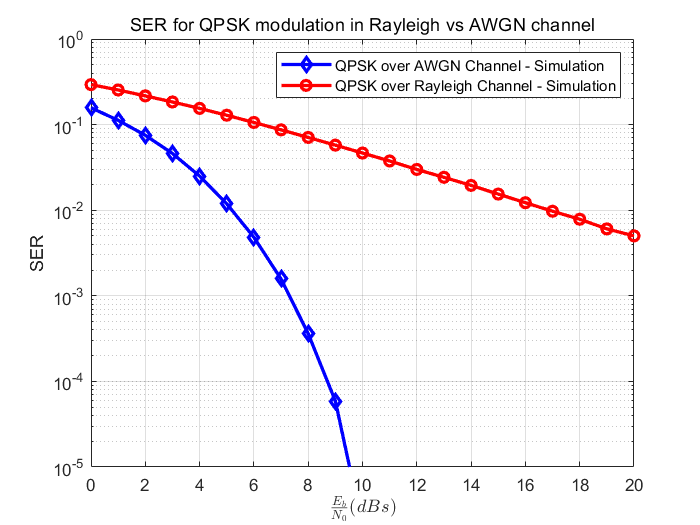

close all;
clc;

% Number of bits to be transmitted
N = 10^6;

%QPSK signal generation

inputSig1 = rand(1,N) > 0.5;
convertedSig1 = 2*inputSig1 - 1; % Converting 0,1 to -1,1

inputSig2 = rand(1,N) > 0.5;
convertedSig2 = 2*inputSig2 - 1; % Converting 0,1 to -1,1

convertedSig = convertedSig1 + 1i*convertedSig2; % si + j*sq (IQ signal)

Eb_N0_db = (0:20); % SNR range in decibels

for i = 1:length(Eb_N0_db)
    
    noise = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N)); % AWGN Noise
    addingNoise = power(10,-Eb_N0_db(i)/20) * noise; % to normalise the noise
    
    h = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N)); %For wireless system the channel shows random behaviour
    
    QPSKsig = convertedSig + addingNoise;
    QPSKsigwireless = h.*convertedSig + addingNoise; % h will be multiplied with signal for wireless comm.
    
    QPSKsigwireless = QPSKsigwireless./h; % to obtain the recieving signal
    
    % To count error, 
    % 1) doing xor of input and recieved signal which will give 1 for error in input signal.
    % 2) count the ones in the xor array.   
    
    % QPSK decoding & counting errors for AWGN channel
    decQPSKsig1 = real(QPSKsig) > 0;
    decQPSKsig2 = imag(QPSKsig) > 0;
    QPSKdiffArr1 = xor(decQPSKsig1,inputSig1);
    QPSKdiffArr2 = xor(decQPSKsig2,inputSig2);
    err1 = sum(QPSKdiffArr1(:)==1);
    err2 = sum(QPSKdiffArr2(:)==1);
    QPSKerr(i) = mean([err1/N err2/N]);
    
    % QPSK decoding & counting errors for wireless channel
    decQPSKsig1wireless = real(QPSKsigwireless) > 0;
    decQPSKsig2wireless = imag(QPSKsigwireless) > 0;
    QPSKdiffArr1wireless = xor(decQPSKsig1wireless,inputSig1);
    QPSKdiffArr2wireless = xor(decQPSKsig2wireless,inputSig2);
    err1wireless = sum(QPSKdiffArr1wireless(:)==1);
    err2wireless = sum(QPSKdiffArr2wireless(:)==1);
    QPSKerrwireless(i) = mean([err1wireless/N err2wireless/N]);
    
end

QPSKser = 2*QPSKerr; % Symbol Rate
QPSKserwireless = 2*QPSKerrwireless; % Symbol Rate for wireless


close all;

figure;
semilogy(Eb_N0_db,QPSKser,"bd-",'LineWidth',2); % Plotting QPSK
hold on
semilogy(Eb_N0_db,QPSKserwireless,"ro-",'LineWidth',2); % Plotting QPSK for wireless
hold off;
grid on
axis([0 20 10^-5 1]);
legend('QPSK over AWGN Channel - Simulation','QPSK over Rayleigh Channel - Simulation');
title('SER for QPSK modulation in Rayleigh vs AWGN channel','FontWeight','Normal');
xlabel('$\frac{E_b}{N_0} (dBs)$','Interpreter','latex');
ylabel('SER');

Lab Assignment 3

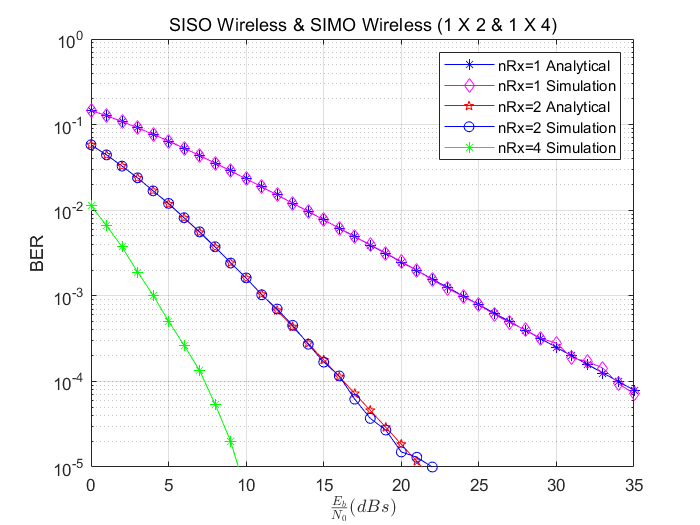

close all;
clc;

% Number of bits to be transmitted
N = 10^6;

% Range of SNR
Eb_N0_dB = 0:35;
Eb_N0_linear = power(10,Eb_N0_dB/10);

% Analytical BER for Rayleigh Wireless Channel for SISO
nRx_1_analytical = 0.5*(1-sqrt(Eb_N0_linear./(Eb_N0_linear + 1)));

mu = sqrt(Eb_N0_linear./(Eb_N0_linear + 1));

% Analytical BER for Wireless Channel for SIMO ( 1 transmitter & 2 reciever)
nRx_2_analytical = 1/4*(2 - 3*mu + mu.^3);

% Generating signal
bits = rand(1,N)>0;
signal = 2*bits - 1; % BPSK modulation

for i=1:length(Eb_N0_dB)
    
    % AWGN noice generation
    n1 = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N));
    n2 = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N));
    n3 = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N));
    n4 = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N));
    
    % channel gain generation
    h1 = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N)); 
    h2 = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N));
    h3 = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N));
    h4 = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N));
    
    % normalising gain on basis of SNR value
    p = power(10,-Eb_N0_dB(i)/20);
    
    % Signal at the recieving end
    y1 = h1.*signal + p*n1;
    y2 = h2.*signal + p*n2;
    y3 = h3.*signal + p*n3;
    y4 = h4.*signal + p*n4;
    
    % Recieved signal for SISO wireless
    rnRx_1 = y1./h1;
    
    % Recieved signal for SIMO wireless ( 1 x 2 )
    rnRx_2 = conj(h1).*y1 + conj(h2).*y2;
    
    % Recieved signal for SIMO wireless ( 1 x 4 )
    rnRx_4 = conj(h1).*y1 + conj(h2).*y2 + conj(h3).*y3 + conj(h4).*y4;
    
    % The following code decodes the signal by taking the real part and
    % counting the error bits.
    dbnRx_1 = real(rnRx_1) >0;
    dfnRx_1 = xor(dbnRx_1,bits);
    BER_nRx_1(i)=sum(dfnRx_1(:)==1); % Error count for SISO wireless
    
    dbnRx_2 = real(rnRx_2) >0;
    dfnRx_2 = xor(dbnRx_2,bits);
    BER_nRx_2(i)=sum(dfnRx_2(:)==1); % Error count for SIMO wireless (1x2)
    
    dbnRx_4 = real(rnRx_4) >0;
    dfnRx_4 = xor(dbnRx_4,bits);
    BER_nRx_4(i)=sum(dfnRx_4(:)==1); % Error count for SIMO wireless (1x4)
end

% BER calculation
BER_nRx_1_simulation = BER_nRx_1/N;
BER_nRx_2_simulation = BER_nRx_2/N;
BER_nRx_4_simulation = BER_nRx_4/N;

% Plots
close all;
figure;
semilogy(Eb_N0_dB,nRx_1_analytical,'b*-');
hold on
semilogy(Eb_N0_dB,BER_nRx_1_simulation,'md-');
hold on
semilogy(Eb_N0_dB,nRx_2_analytical,'rp-');
hold on
semilogy(Eb_N0_dB,BER_nRx_2_simulation,'bo-');
hold on
semilogy(Eb_N0_dB,BER_nRx_4_simulation,'g*-');
hold off
grid on
axis([0 35 10^-5 1]);
legend('nRx=1 Analytical','nRx=1 Simulation','nRx=2 Analytical','nRx=2 Simulation','nRx=4 Simulation');
title('SISO Wireless & SIMO Wireless (1 X 2 & 1 X 4)','FontWeight','Normal');
xlabel('$\frac{E_b}{N_0} (dBs)$','Interpreter','latex');
ylabel('BER');

Lab Assignment 4

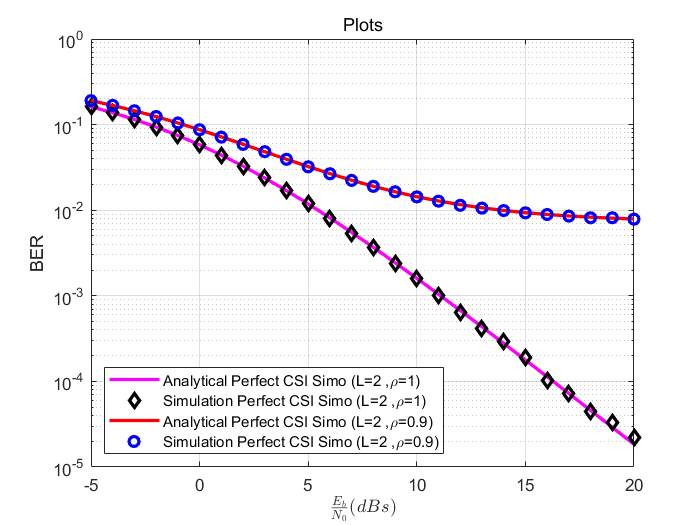

close all;
clc;

% Number of bits to be transmitted
N = 10^6;

% SNR Range
Eb_N0_dB = (-5:20);
% Conversion of dBs to linear scale
Eb_N0_linear = power(10,Eb_N0_dB/10);


mu = sqrt(Eb_N0_linear./(Eb_N0_linear + 1));

% ro1 is for the imperfect CSI
ro1 = 0.9;
%ro2 is for the perfect CSI
ro2 = 1;

% analytical formula to find BER for SIMO having perfect CSI (becuse ro = 1)
analytical_pscsi_simo = 1/4*(2 - 3*ro2*mu + power(ro2*mu,3));

% analytical formula to find BER for SIMO having perfect CSI (becuse ro = 0.9)
analytical_icsi_simo = 1/4*(2 - 3*ro1*mu + power(ro1*mu,3));

% Generating input signal
input = rand(1,N)>0.5;
% BPSK modulation
signal = 2*input - 1;

for i=1:length(Eb_N0_dB)
    % AWGN Noise generation
    n1 = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N)); 
    n2 = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N));
    
    % generating rayleigh random variable which is modelled for the channel coefficient
    hh1 = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N));
    hh2 = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N));
    
    % generating the channel coefficient for the given value of ro = 1 (perfect csi) and generated h for Rx no. 1
    h1 =  ro2*hh1 + sqrt(1-ro2^2)*1/sqrt(2)*(randn(1,N) + 1i*randn(1,N));
    % generating the channel coefficient for the given value of ro = 1 (perfect csi) and generated h for Rx no. 2
    h2 =  ro2*hh2 + sqrt(1-ro2^2)*1/sqrt(2)*(randn(1,N) + 1i*randn(1,N));
    
    % generating the channel coefficient for the given value of ro = 0.9 (imperfect csi) and generated h for Rx no. 1
    h3 =  ro1*hh1 + sqrt(1-ro1^2)*1/sqrt(2)*(randn(1,N) + 1i*randn(1,N));
    % generating the channel coefficient for the given value of ro = 0.9 (imperfect csi) and generated h for Rx no. 2
    h4 =  ro1*hh2 + sqrt(1-ro1^2)*1/sqrt(2)*(randn(1,N) + 1i*randn(1,N));
    

    p = power(10,(-Eb_N0_dB(i)/20));
    
    % recieved signal at reciever 1 along with the noise for ro = 1 (perfect csi)
    y1_pcsi = h1.*signal + p*n1;
    % recieved signal at reciever 2 along with the noise for ro = 1 (perfect csi)
    y2_pcsi = h2.*signal + p*n2;
    
    % recieved signal at reciever 1 along with the noise for ro = 0.9 (imperfect csi)
    y1_icsi = h3.*signal + p*n1;
    % recieved signal at reciever 2 along with the noise for ro = 0.9 (imperfect csi)
    y2_icsi = h4.*signal + p*n2;
    
    % using the detection rule for SIMO Wireless system for both perfect & imperfect csi
    y_pcsi = conj(h1).*y1_pcsi + conj(h2).*y2_pcsi;
    y_icsi = conj(hh1).*y1_icsi + conj(hh2).*y2_icsi; % here we are taking h1 & h2 as it is imperfect csi we don't know the values of h at reciever end
    
    % Applying MLD rule
    rsig_pcsi = real(y_pcsi) >= 0;
    % counting errors
    nerr_pcsi(i) = size(find([input-rsig_pcsi]), 2);
    
    % Applying MLD rule
    rsig_icsi = real(y_icsi) >= 0;
    % counting errors
    nerr_icsi(i) =  size(find([input-rsig_icsi]), 2);
    
end

% BER Calculation
ber_pcsi = nerr_pcsi/N;
ber_icsi = nerr_icsi/N;

% Plots
close all;
figure;
semilogy(Eb_N0_dB,analytical_pscsi_simo,'m.-','LineWidth',2);
hold on
semilogy(Eb_N0_dB,ber_pcsi,'kd','LineWidth',2);
hold on
semilogy(Eb_N0_dB,analytical_icsi_simo,'r-','LineWidth',2);
hold on
semilogy(Eb_N0_dB,ber_icsi,'bo','LineWidth',2);
hold off
grid on
axis([-5 20 10^-5 1]);
LOC = "southwest";
legend('Analytical Perfect CSI Simo (L=2 ,\rho=1)','Simulation Perfect CSI Simo (L=2 ,\rho=1)','Analytical Perfect CSI Simo (L=2 ,\rho=0.9)','Simulation Perfect CSI Simo (L=2 ,\rho=0.9)','Location',LOC);
title('Plots','FontWeight','Normal');
xlabel('$\frac{E_b}{N_0} (dBs)$','Interpreter','latex');
ylabel('BER');

Lab Assignment 5

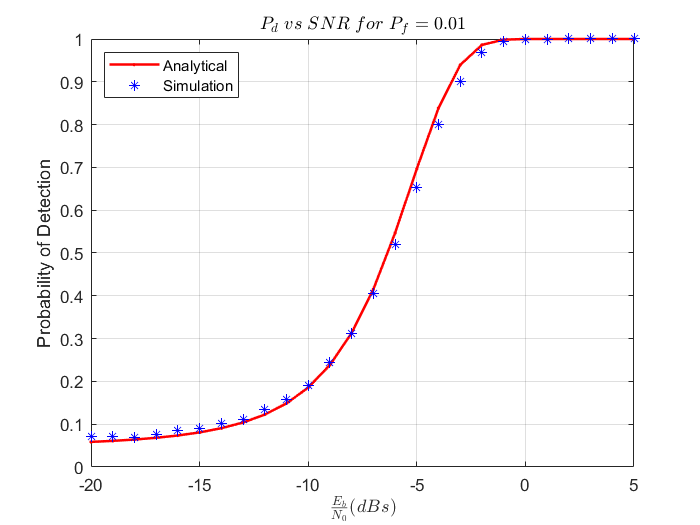

close all;
clc;

L = 100; % u (Channel Length)
false_alarm_probability = 0.01; % Assumed probability of fasle alarm used for determining threshold value
threshold = (qfuncinv(false_alarm_probability)./sqrt(L))+1; % calculating threshold from Pf
snr_dB = -20:5; % range of SNR
snr_linear = power(10,snr_dB/10); % Converting value of SNR from dBs to linear

for i=1:length(snr_dB)
    detection = 0; % initialising with 0
    for k=1:10000 % Number of Monte-Carlo Simulations
        noise = randn(1,L); % noise generation (Real AWGN Noise)
        signal = sqrt(snr_linear(i)).*randn(1,L); % Input signal*gain
        rsignal = signal+noise; % received signal
        energy = power(abs(rsignal),2); % Energy Calculation
        test_statistic = sum(energy)/L; % Calculating the Test Statistic
        if(test_statistic >= threshold) % using the definition of probability of detection
            detection = detection + 1;
        end
    end
    Pd_simulation(i) = detection / k; % calculating detection probability
end

numerator = L.*(threshold - (snr_linear+1));
denominator = sqrt(2*L*(snr_linear+1));
Pd_analytical = qfunc(numerator./denominator); % analytical formula for finding Pd

close all;
plot(snr_dB,Pd_analytical,'r.-','LineWidth',1.5);
hold on
plot(snr_dB,Pd_simulation,'b*');
axis([-20 5 0 1])

LOC = "northwest";
legend('Analytical','Simulation','Location',LOC);
title('$P_{d} \;vs\; SNR \;for\; P_{f} = 0.01$','Interpreter','latex','FontWeight','Normal');
xlabel('$\frac{E_b}{N_0} (dBs)$','Interpreter','latex');
ylabel('Probability of Detection');
grid on

Lab Assingment 6

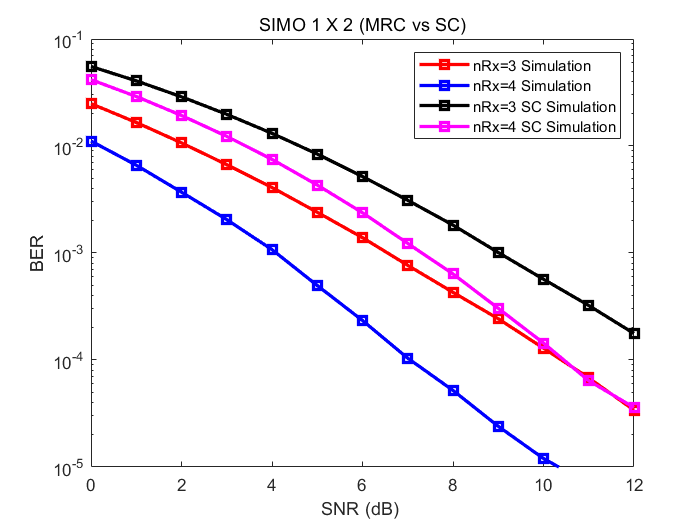

close all;
clc;

% Number of bits to be transmitted
N = 10^6;

% Range of SNR
Eb_N0_dB = 0:12;
Eb_N0_linear = power(10,Eb_N0_dB/10);

% Generating signal
bits = rand(1,N)>0;
signal = 2*bits - 1; % BPSK modulation

% AWGN noice generation
n1 = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N));
n2 = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N));
n3 = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N));
n4 = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N));

% channel gain generation
h1 = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N)); 
h2 = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N));
h3 = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N)); 
h4 = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N));

for i=1:length(Eb_N0_dB)
    
    % normalising gain on basis of SNR value
    p = power(10,-Eb_N0_dB(i)/20);
    
    % Signal at the recieving end
    y1 = h1.*signal + p*n1;
    y2 = h2.*signal + p*n2;
    y3 = h3.*signal + p*n3;
    y4 = h4.*signal + p*n4;
    
    % Recieved signal for SIMO wireless ( 1 x 3 )
    rnRx_3 = conj(h1).*y1 + conj(h2).*y2 + conj(h3).*y3;
    % Recieved signal for SIMO wireless ( 1 x 4 )
    rnRx_4 = conj(h1).*y1 + conj(h2).*y2 + conj(h3).*y3 + conj(h4).*y4;
    
    % Channel Power
    H1 = h1.*conj(h1);
    H2 = h2.*conj(h2);
    H3 = h3.*conj(h3);
    H4 = h4.*conj(h4);
    
    % Antenna Detection Rule for both 1x3 & 1x4 SIMO Selection Combining
    for j=1:N
        
        % Calculating the max energy for SC 1x3 & 1x4 SC
        max_energy_rx3 = max([H1(j),H2(j),H3(j)]);
        max_energy_rx4 = max([H1(j),H2(j),H3(j),H4(j)]);
        
        % Antenna Selection rule for 1x3 SC
        if(max_energy_rx3 == H1(j))
            channel_gain_rx3(j) = h1(j);
            recieved_signal_rx3(j) = y1(j);
        elseif(max_energy_rx3 == H2(j))
            channel_gain_rx3(j) = h2(j);
            recieved_signal_rx3(j) = y2(j);
        else
            channel_gain_rx3(j) = h3(j);
            recieved_signal_rx3(j) = y3(j);
        end
        
        % Antenna Selection rule for 1x4 SC
        if(max_energy_rx4 == H1(j))
            channel_gain_rx4(j) = h1(j);
            recieved_signal_rx4(j) = y1(j);
        elseif(max_energy_rx4 == H2(j))
            channel_gain_rx4(j) = h2(j);
            recieved_signal_rx4(j) = y2(j);
        elseif(max_energy_rx4 == H3(j))
            channel_gain_rx4(j) = h3(j);
            recieved_signal_rx4(j) = y3(j);
        else
            channel_gain_rx4(j) = h4(j);
            recieved_signal_rx4(j) = y4(j);
        end
     
    end    
    
    % Using the detection rule for SIMO SC after applying the antenna rule
    dec_rx4 = conj(channel_gain_rx4).*recieved_signal_rx4;
    dec_rx3 = conj(channel_gain_rx3).*recieved_signal_rx3;
    
    % The following code decodes the signal by taking the real part and
    % counting the error bits. for SC
    dbnRx_4_SC = real(dec_rx4) >0;
    dfnRx_4_SC = xor(dbnRx_4_SC,bits);
    BER_nRx_4_SC(i)=sum(dfnRx_4_SC(:)==1);
    
    dbnRx_3_SC = real(dec_rx3) >0;
    dfnRx_3_SC = xor(dbnRx_3_SC,bits);
    BER_nRx_3_SC(i)=sum(dfnRx_3_SC(:)==1);
    
    % The following code decodes the signal by taking the real part and
    % counting the error bits for MRC.
    
    dbnRx_4 = real(rnRx_4) >0;
    dfnRx_4 = xor(dbnRx_4,bits);
    BER_nRx_4(i)=sum(dfnRx_4(:)==1); % Error count for SIMO wireless (1x2)
    
    dbnRx_3 = real(rnRx_3) >0;
    dfnRx_3 = xor(dbnRx_3,bits);
    BER_nRx_3(i)=sum(dfnRx_3(:)==1); % Error count for SIMO wireless (1x2)
    
end

% BER Calculation
BER_nRx_3_simulation = BER_nRx_3/N;
BER_nRx_4_simulation = BER_nRx_4/N;
BER_nRx_3_SC_simulation = BER_nRx_3_SC/N;
BER_nRx_4_SC_simulation = BER_nRx_4_SC/N;

% Plots
close all;
figure;
semilogy(Eb_N0_dB,BER_nRx_3_simulation,'rs-','LineWidth',2);
hold on
semilogy(Eb_N0_dB,BER_nRx_4_simulation,'bs-','LineWidth',2);
hold on
semilogy(Eb_N0_dB,BER_nRx_3_SC_simulation,'ks-','LineWidth',2);
hold on
semilogy(Eb_N0_dB,BER_nRx_4_SC_simulation,'ms-','LineWidth',2);
hold off

axis([0 12 10^-5 10^-1]);
legend('nRx=3 Simulation','nRx=4 Simulation','nRx=3 SC Simulation','nRx=4 SC Simulation');
title('SIMO 1 X 2 (MRC vs SC)','FontWeight','Normal');
xlabel('SNR (dB) ');
ylabel('BER');